% DC Motor Model

R = 2.0;                % Ohms
L = 0.5;                % Henrys
Km = 1.5;               % torque constant
Kb = 0.1;               % back emf constant
Kf = 0.2;               % Nms
J = 0.02;               % kg.m^2/s^2

h1 = tf(Km,[L R]);            % armature
h2 = tf(1,[J Kf]);            % eqn of motion

dcm = ss(h2) * [h1 , 1];      % w = h2 * (h1*Va + Td)
dcm = feedback(dcm,Kb,1,1)   % close back emf loop


dcm =
 
  A = 
          x1     x2
   x1    -10     12
   x2  -1.25     -4
 
  B = 
       u1  u2
   x1   0   8
   x2   2   0
 
  C = 
         x1    x2
   y1  6.25     0
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.



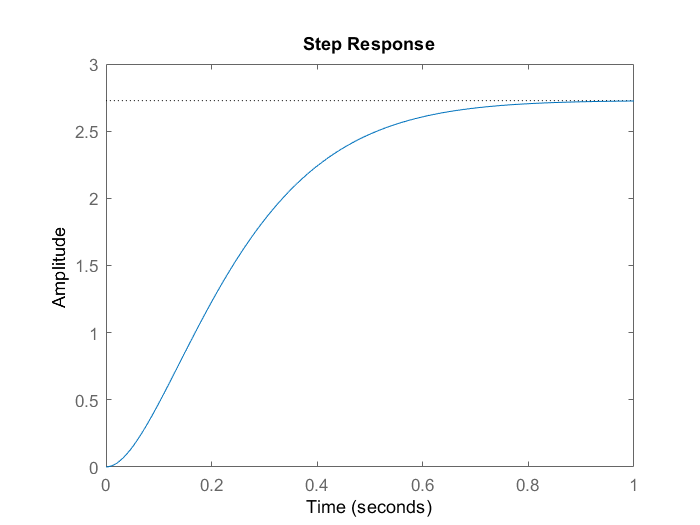


system_TF = tf(dcm);

stepplot(dcm(1));